# Experiment 6

This Live Script contains the 5-step experimental setup described in the section: *"2.8.3.2. Accuracy for unbalanced distribution system", *included in the dissertation:

W. González-Vanegas,** "Planning Methodologies for the Operation and Expansion of Distribution Systems Considering the Interactions with the Transmission System"**, Ph.D. dissertation, Dept. of Elect. Electron. and Comp. Eng., National University of Colombia, Manizales, Caldas, 2025.

*Note: MATLAB R2023a is the oldest version where this Live Script was successfully tested. *

*Bibliography cited in this Live Script:*

*[1] ***W. H. Kersting,** ***Distribution System Modeling and Analysis***, 4th Edition. Boca Raton, FL: CRC Press, 2018

*[2] ***IEEE Distribution System Analysis Subcommittee,** *"Radial Distribution Test Feeders"*. [Online]. Available: [https://ewh.ieee.org/soc/pes/dsacom/testfeeders/testfeeders.pdf](https://ewh.ieee.org/soc/pes/dsacom/testfeeders/testfeeders.pdf) (Accessed: Nov. 11, 2025).

Figure 1 shows the spacing of conductors of phases a, b, c, and the neutral, identified with the ID-500 code, according to the feeder data for overhead lines of IEEE. The base case of this configuration holds: $$x_1=2.5\;ft,\quad x_2=4.5\;ft,\quad x_3=0.5\;ft,\quad y_1=24\;ft,\quad y_2=4\;ft.$$

*Fig 1.  ID-500 IEEE line configuration.* 

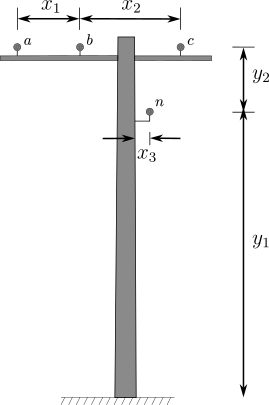

To explore different line parameters that fall in relistic ranges, we modifiy the spacing between conductors and compute the modified Carson equations to get the resistance, rectance, and capacitance of the line. With $x_3$ and $y_2$ fixed at its base case values, the explored ranges for the other distances are as follows:


$$$x_1\in\{2.0, 2.5, 3.0, 3.5 \}\; ft$$$



$$$x_2\in\{3.0, 4.0, 5.0, 6.0, 7.0, 8.0, 9.0, 10.0 \}\; ft$$$



$$$y_1\in\{20, 22, 24, 26, 28 \}\; ft$$$



$$$y_2\in\{1.0, 2.0, 3.0, 4.0, 5.0, 6.0 \}\; ft$$$


Notice that these values yield 378 different configuations as follows:

clear
scenarios = combinations((2:0.5:3.5), (3:10), (20:2:28), (1:6));
scenarios.Properties.VariableNames = {'x1', 'x2', 'y1', 'y2'};

We take the data for conductor **#2 6/1 ACSR **from [1], which corresponds to distribution line **834 - 860** of the IEEE 34-bus feeder [2]:

cond_n2_61_ACSR = struct('r', 1.69, ...                 % Ohm/mile
                         'GMR', 0.00418, ...            % ft
                         'radius', (0.316*(1/12))/2);   % ft

cond_n5_61_ACSR = struct('r', 3.18, ...                 % Ohm/mile
                         'GMR', 0.00416, ...            % ft
                         'radius', (0.223*(1/12))/2);   % ft

Now, we loop through all the scenario configurations and run a power flow under the exact AC, QTPC, and LTPC formulations:

nsce = size(scenarios,1);
R = zeros(3,3,nsce);
X = zeros(3,3,nsce);
C = zeros(3,3,nsce);
x3 = 0.5;

for s = 1:nsce
    x1 = scenarios(s,:).x1;
    x2 = scenarios(s,:).x2;
    y1 = scenarios(s,:).y1;
    y2 = scenarios(s,:).y2;

    data_phases = cond_n2_61_ACSR;
    data_phases.position = [1j*(y1+y2) x1+1j*(y1+y2) x1+x2+1j*(y1+y2)].';

    data_neutrals = cond_n2_61_ACSR;
    data_neutrals.position = 0.5*(x1+x2)+x3+1j*y1;

    data = struct('phases', data_phases,'neutrals', data_neutrals);  % Create struct of conductors info
 
    [R(:,:,s), X(:,:,s), C(:,:,s)] = modified_carson(data);          % Compute modified Carson equations   
end

Bonus: we compute the operating ranges for the diagonal and off-diagonal values of the resistance, reactance and capacitance primitive matrices:

mpc3p = case1line_ieee34;
diag_R = [R(1,1,:) R(2,2,:) R(3,3,:)]; diag_R = diag_R(:);
diag_X = [X(1,1,:) X(2,2,:) X(3,3,:)]; diag_X = diag_X(:);
diag_C = [C(1,1,:) C(2,2,:) C(3,3,:)]; diag_C = diag_C(:)*1e3;
R_ab = R(1,2,:); R_ab = R_ab(:);
R_ac = R(1,3,:); R_ac = R_ac(:);
R_bc = R(2,3,:); R_bc = R_bc(:);
X_ab = X(1,2,:); X_ab = X_ab(:);
X_ac = X(1,3,:); X_ac = X_ac(:);
X_bc = X(2,3,:); X_bc = X_bc(:);
C_ab = C(1,2,:); C_ab = C_ab(:)*1e3;
C_ac = C(1,3,:); C_ac = C_ac(:)*1e3;
C_bc = C(2,3,:); C_bc = C_bc(:)*1e3;

min_diagR = min(diag_R); min_factor_diagR = min_diagR/mean(mpc3p.lc([2 5 7]));
max_diagR = max(diag_R); max_factor_diagR = max_diagR/mean(mpc3p.lc([2 5 7]));
min_diagX = min(diag_X); min_factor_diagX = min_diagX/mean(mpc3p.lc([8 11 12]));
max_diagX = max(diag_X); max_factor_diagX = max_diagX/mean(mpc3p.lc([8 11 12]));
min_diagC = min(diag_C); min_factor_diagC = min_diagC/mean(mpc3p.lc([14 17 19]));
max_diagC = max(diag_C); max_factor_diagC = max_diagC/mean(mpc3p.lc([14 17 19]));

min_Rab = min(R_ab); min_factor_Rab = min_Rab/mpc3p.lc(3);
max_Rab = max(R_ab); max_factor_Rab = max_Rab/mpc3p.lc(3);
min_Xab = min(X_ab); min_factor_Xab = min_Xab/mpc3p.lc(9);
max_Xab = max(X_ab); max_factor_Xab = max_Xab/mpc3p.lc(9);
min_Cab = min(abs(C_ab)); min_factor_Cab = min_Cab/abs(mpc3p.lc(15));
max_Cab = max(abs(C_ab)); max_factor_Cab = max_Cab/abs(mpc3p.lc(15));

min_Rac = min(R_ac); min_factor_Rac = min_Rac/mpc3p.lc(4);
max_Rac = max(R_ac); max_factor_Rac = max_Rac/mpc3p.lc(4);
min_Xac = min(X_ac); min_factor_Xac = min_Xac/mpc3p.lc(10);
max_Xac = max(X_ac); max_factor_Xac = max_Xac/mpc3p.lc(10);
min_Cac = min(abs(C_ac)); min_factor_Cac = min_Cac/abs(mpc3p.lc(16));
max_Cac = max(abs(C_ac)); max_factor_Cac = max_Cac/abs(mpc3p.lc(16));

min_Rbc = min(R_bc); min_factor_Rbc = min_Rbc/mpc3p.lc(6);
max_Rbc = max(R_bc); max_factor_Rbc = max_Rbc/mpc3p.lc(6);
min_Xbc = min(X_bc); min_factor_Xbc = min_Xbc/mpc3p.lc(12);
max_Xbc = max(X_bc); max_factor_Xbc = max_Xbc/mpc3p.lc(12);
min_Cbc = min(abs(C_bc)); min_factor_Cbc = min_Cbc/abs(mpc3p.lc(18));
max_Cbc = max(abs(C_bc)); max_factor_Cbc = max_Cbc/abs(mpc3p.lc(18));

min_R = [min_factor_diagR    min_factor_Rab         min_factor_Rac
         min_factor_Rab      min_factor_diagR       min_factor_Rbc
         min_factor_Rac      min_factor_Rbc         min_factor_diagR]
max_R = [max_factor_diagR     max_factor_Rab         max_factor_Rac
         max_factor_Rab       max_factor_diagR       max_factor_Rbc
         max_factor_Rac       max_factor_Rbc         max_factor_diagR]
min_X = [min_factor_diagX    min_factor_Xab         min_factor_Xac
         min_factor_Xab      min_factor_diagX       min_factor_Xbc
         min_factor_Xac      min_factor_Xbc         min_factor_diagX]
max_X = [max_factor_diagX     max_factor_Xab         max_factor_Xac
         max_factor_Xab       max_factor_diagX       max_factor_Xbc
         max_factor_Xac       max_factor_Xbc         max_factor_diagX]
min_C = [min_factor_diagC    min_factor_Cab         min_factor_Cac
         min_factor_Cab      min_factor_diagC       min_factor_Cbc
         min_factor_Cac      min_factor_Cbc         min_factor_diagC]
max_C = [max_factor_diagC     max_factor_Cab         max_factor_Cac
         max_factor_Cab       max_factor_diagC       max_factor_Cbc
         max_factor_Cac       max_factor_Cbc         max_factor_diagC]


function [R, X, C] = modified_carson(data)

%% Unpack data
GMR_phases = data.phases.GMR;
r_phases = data.phases.r;
radius_phases = data.phases.radius;
position_phases = data.phases.position;
if isscalar(GMR_phases)
    GMR_phases = GMR_phases * ones(3,1);
end
if isscalar(r_phases)
    r_phases = r_phases * ones(3,1);
end
if isscalar(radius_phases)
    radius_phases = radius_phases * ones(3,1);
end
if isfield(data,'neutrals')
    GMR_neutrals = data.neutrals.GMR;
    r_neutrals = data.neutrals.r;
    radius_neutrals = data.neutrals.radius;
    position_neutrals = data.neutrals.position(:);
    nneutrals = numel(data.neutrals.position);
    if nneutrals > 1
        if isscalar(GMR_neutrals)
            GMR_neutrals = GMR_neutrals * ones(nneutrals,1);
        end
        if isscalar(r_neutrals)
            r_neutrals = r_neutrals * ones(nneutrals,1);
        end
        if isscalar(radius_neutrals)
            radius_neutrals = radius_neutrals * ones(nneutrals,1);
        end
    end
else
    GMR_neutrals = [];
    r_neutrals = [];
    radius_neutrals = [];
    position_neutrals = [];
    nneutrals = 0;
end

positions = [position_phases; position_neutrals];

%% Matrix of distances
% 1) Diagonal
D_diag_val1 = [GMR_phases; GMR_neutrals]; % Distance on real conductors for impendace matrix
D_diag_val2 = [radius_phases; radius_neutrals]; % Distance on real conductors for shunt admittance matrix 
S_diag_val = imag(positions-conj(positions)); % Distances on images of conductors
D_diag_ii = (1:3+nneutrals)';
D_diag_jj =  D_diag_ii;
% 2) Off-diagonal - upper tringular
nval = numel(positions);
D_offdiag_vals = zeros(0.5*nval*(nval-1),1);
S_offdiag_vals = zeros(0.5*nval*(nval-1),1);
D_offdiag_ii = zeros(0.5*nval*(nval-1),1);
D_offdiag_jj = D_offdiag_ii;
counter = 1;
for i = 1:3+nneutrals
    for j = 1:3+nneutrals
        if j > i
            D_offdiag_ii(counter) = i;
            D_offdiag_jj(counter) = j;
            D_offdiag_vals(counter) = norm(positions(i) - positions(j));
            S_offdiag_vals(counter) = norm(positions(i) - conj(positions(j)));
            counter = counter + 1;
        end
    end
end

%% Impedance matrix (R+jX)
% 1) Diagonal
z_diag = [r_phases; r_neutrals] + 0.09530 + 1j*0.12134*(log(1./D_diag_val1)+7.93402);
% 2) Off-diagonal
z_offdiag = 0.09530+1j*0.12134*(log(1./D_offdiag_vals)+7.93402);
% 3) Build matrix
Z = sparse([D_diag_ii; D_offdiag_ii; D_offdiag_jj], ...
           [D_diag_jj; D_offdiag_jj; D_offdiag_ii], ...
           [z_diag; z_offdiag; z_offdiag]);
Zpp = Z(1:3,1:3);
Znp = Z(4:3+nneutrals,1:3);
Znn = Z(4:3+nneutrals,4:3+nneutrals);
Zpn = Z(1:3,4:3+nneutrals);
% 4) Apply Kron reduction
Zabc = Zpp-Zpn*inv(Znn)*Znp;

%% Shunt admittance matrix
% 1) Matrix of distances on real conductors
D = sparse([D_diag_ii; D_offdiag_ii; D_offdiag_jj], ...
           [D_diag_jj; D_offdiag_jj; D_offdiag_ii], ...
           [D_diag_val2; D_offdiag_vals; D_offdiag_vals]);
S = sparse([D_diag_ii; D_offdiag_ii; D_offdiag_jj], ...
           [D_diag_jj; D_offdiag_jj; D_offdiag_ii], ...
           [S_diag_val; S_offdiag_vals; S_offdiag_vals]);

% 2) Matrix of potential values
P = 11.17689 * log(S./D);
Ppp = P(1:3,1:3);
Pnp = P(4:3+nneutrals,1:3);
Pnn = P(4:3+nneutrals,4:3+nneutrals);
Ppn = P(1:3,4:3+nneutrals);
Pabc = Ppp-Ppn*inv(Pnn)*Pnp;

%% Return parameters
R = real(Zabc); % Ohm/mile
X = imag(Zabc); % Ohm/mile
C = inv(Pabc);  % uF/mile
end

function mpc = case1line_ieee34
% case1line_ieee34 - Line 834-860 of the IEEE 34-bus feeder with a balanced
%   generator connected at the from end (bus  834), and the load of bus 860 
%   connected to it. 
%

%% MATPOWER Case Format : Version 2
mpc.version = '2';

%%-----  Power Flow Data  -----%%
%% system MVA base
mpc.baseMVA = 100;

%% bus data
%	bus_i	type	Pd	Qd	Gs	Bs	area	Vm	Va	baseKV	zone	Vmax	Vmin
mpc.bus = [];

%% generator data
%	bus	Pg	Qg	Qmax	Qmin	Vg	mBase	status	Pmax	Pmin	Pc1	Pc2	Qc1min	Qc1max	Qc2min	Qc2max	ramp_agc	ramp_10	ramp_30	ramp_q	apf
mpc.gen = [];

%% branch data
%	fbus	tbus	r	x	b	rateA	rateB	rateC	ratio	angle	status	angmin	angmax
mpc.branch = [];
mpc.gencost = [];

%%-----  3 Phase Model Data  -----%%
%% system data
mpc.freq = 60;      %% frequency, Hz
mpc.basekVA = 1000; %% system kVA base

%% 3-phase bus data
%	busid	type	basekV	Vm1	Vm2	Vm3	Va1	Va2	Va3
mpc.bus3p = [
	1	3	24.9*sqrt(3)	1	1	1	0	-120	120;
	2	1	24.9*sqrt(3)	1	1	1	0	-120	120;	
];

%% buslink data
%	linkid	busid	bus3pid	status
mpc.buslink = [];

%% 3-phase line data
%	brid	fbus	tbus	status	lcid	len
mpc.line3p = [
	1	1	2	1	1	65600/5280;	
];

%% 3-phase transformer data
%	xfid	fbus	tbus	status	R	X	basekVA	basekV	ratio
mpc.xfmr3p = [];

%% 3-phase shunt data
%	shid	shbus	status	gs1	gs2	gs3	bs1	bs2	bs3
mpc.shunt3p = [];

%% 3-phase load data
%	ldid	ldbus	status	Pd1	Pd2	Pd3	ldpf1	ldpf2	ldpf3
mpc.load3p = [
	1	2	1	1500	1500	1500	0.78	0.78	0.78;
];

%% 3-phase generator data
%	genid	gbus	status	Vg1	Vg2	Vg3	Pg1	Pg2	Pg3	Qg1	Qg2	Qg3
mpc.gen3p = [
	1	1	1	1	1	1	0	0	0	0	0	0;
];

%% line construction data
%	lcid	R11	R21	R31	R22	R32	R33	X11	X21	X31	X22	X32	X33	C11	C21	C31	C22	C32	C33
mpc.lc = [
	1	1.9300	0.2327	0.2359	1.9157	0.2288	1.9219	1.4115	0.6442	0.5691	1.4281	0.5238	1.4209	85.3450	-23.9400	-15.6700	81.7583	-9.9183	78.5900;
];    
end